% 单位转换常数定义
unit = 0.9144;      % 1单位 = 0.9144米 
feet = 0.3048;      % 1英尺 = 0.3048米
inch = 0.0254;      % 1英寸 = 0.0254米

function res = A(i, j, k)
    feet = 0.3048;      % 1英尺对应的米数
    inch = 0.0254;      % 1英寸对应的米数
    % 计算总长度：英尺转换 + 英寸转换 + 1/8英寸转换
    res = i * feet + j * inch + k * inch * 0.125;
end

% 使用unit作为基本单位，从1到11个单位位置
x = [1*unit 2*unit 3*unit 4*unit 5*unit 6*unit 7*unit 8*unit 9*unit 10*unit 11*unit];

% 吃水线到中轴的距离
Bushwark = [A(3,3,6) A(3,1,6) A(6,2,7) A(6,9,2) A(7,0,2) A(7,0,4) A(6,10,4) A(6,7,6) A(6,2,4) A(5,8,0) A(5,1,0)];
y_18Ab = [A(2,4,0) A(4,9,4) A(6,1,2) A(6,8,4) 0 0 0 0 0 A(5,8,2) A(5,2,0)];
y_12Ab = [A(2,1,0) A(4,7,3) A(5,11,2) A(6,7,2) A(6,11,6) A(6,10,6) A(6,9,2) A(6,7,0) A(6,2,0) A(5,7,4) A(5,1,3)];
y_6Ab = [A(1,8,0) A(4,4,4) A(5,9,6) A(6,6,0) A(6,10,6) A(6,10,2) A(6,9,0) A(6,6,6) A(6,0,4) A(5,5,7) A(4,10,3)];
DWL = [A(1,1,6) A(4,0,4) A(5,6,2) A(6,3,7) A(6,8,6) A(6,10,0) A(6,8,6) A(6,5,4) A(6,0,0) A(5,3,0) A(3,9,4)];
y_6B = [A(0,7,4) A(3,5,4) A(5,1,2) A(6,0,5) A(6,5,4) A(6,7,2) A(6,5,7) A(6,1,0) A(5,5,4) A(4,2,0) A(0,11,4)];
y_12B = [0 A(2,8,3) A(4,4,2) A(5,4,1) A(5,11,1) A(6,1,2) A(5,10,0) A(5,3,4) A(4,1,4) A(2,0,7) 0];
y_18B = [0 A(1,8,4) A(3,3,4) A(4,3,2) A(4,8,6) A(4,11,0) A(5,6,4) A(3,9,0) A(2,5,0) A(0,10,4) 0];
y_24B = [0 A(0,9,6) A(2,0,2) A(2,5,4) A(3,3,4) A(3,4,6) A(2,0,2) A(2,3,4) A(1,3,4) A(0,6,4) 0];
y_30B = [0 0 A(0,6,2) A(1,1,2) A(1,6,6) A(1,7,4) A(1,7,2) A(1,2,6) A(0,8,6) A(0,4,4) 0];
Keel = [A(0,3,0) A(0,3,0) A(0,3,0) 0 0 0 0 0 0 A(0,3,0) 0];

delta_h = 0.1524; % 每条线之间的高度差

% 准备3D数据点 - 只使用有效的非零数据点
z_levels = 0:delta_h:delta_h*10; % 11个高度层
z_levels = max(z_levels) - z_levels; % 翻转Z坐标，让船正放

% 收集所有有效数据点（右舷）
X_data = [];
Y_data = [];
Z_data = [];

lines = {Bushwark, y_18Ab, y_12Ab, y_6Ab, DWL, y_6B, y_12B, y_18B, y_24B, y_30B, Keel};
line_names = {'Bushwark', '18Ab', '12Ab', '6Ab', 'DWL', '6B', '12B', '18B', '24B', '30B', 'Keel'};

for i = 1:length(lines)
    current_line = lines{i};
    for j = 1:length(x)
        if current_line(j) ~= 0 % 只使用非零数据点
            X_data = [X_data; x(j)];
            Y_data = [Y_data; current_line(j)];
            Z_data = [Z_data; z_levels(i)];
        end
    end
end



% 定义切片数量
num_slices = 100;  % 沿船长方向的切片数量

% 创建更密集的站位网格
x_dense = linspace(min(x), max(x), num_slices);

% 为每个密集站位插值半宽值
Y_dense = zeros(length(z_levels), num_slices);

for i = 1:length(z_levels)
    % 获取当前高度层的有效数据点
    z_mask = (Z_data == z_levels(i));
    x_current = X_data(z_mask);
    y_current = Y_data(z_mask);
    
    if length(x_current) > 1
        % 使用样条插值获得光滑曲线
        Y_dense(i, :) = interp1(x_current, y_current, x_dense, 'spline', 'extrap');
    else
        % 如果数据点不足，使用线性外推
        Y_dense(i, :) = interp1(x_current, y_current, x_dense, 'linear', 'extrap');
    end
    
    % 确保半宽非负
    Y_dense(i, :) = max(0, Y_dense(i, :));
end

% 计算切片面积和体积
slice_areas = zeros(1, num_slices);
slice_volumes = zeros(1, num_slices);
slice_centers_x = zeros(1, num_slices);
slice_centers_z = zeros(1, num_slices);

for i = 1:num_slices
    % 使用梯形法则计算当前切片的面积
    area = 0;
    for j = 1:length(z_levels)-1
        % 计算两个高度层之间的梯形面积
        y1 = Y_dense(j, i);
        y2 = Y_dense(j+1, i);
        dz = z_levels(j) - z_levels(j+1);  % 注意z是递减的
        
        area = area + (y1 + y2) * dz / 2;
    end
    slice_areas(i) = 2 * area;  % 乘以2因为只计算了右舷
    
    % 计算切片体积（假设厚度为dx）
    if i == 1
        dx = (x_dense(2) - x_dense(1)) / 2;
    elseif i == num_slices
        dx = (x_dense(end) - x_dense(end-1)) / 2;
    else
        dx = (x_dense(i+1) - x_dense(i-1)) / 2;
    end
    
    slice_volumes(i) = slice_areas(i) * dx;
    slice_centers_x(i) = x_dense(i);
    
    % 计算切片质心的z坐标
    z_moment = 0;
    for j = 1:length(z_levels)-1
        y1 = Y_dense(j, i);
        y2 = Y_dense(j+1, i);
        dz = z_levels(j) - z_levels(j+1);
        z_avg = (z_levels(j) + z_levels(j+1)) / 2;
        
        z_moment = z_moment + (y1 + y2) * dz / 2 * z_avg;
    end
    slice_centers_z(i) = z_moment / area;
end

% 计算整体质心
total_volume = sum(slice_volumes);
center_of_mass_x = sum(slice_volumes .* slice_centers_x) / total_volume;
center_of_mass_z = sum(slice_volumes .* slice_centers_z) / total_volume;

fprintf('船体质心计算结果:\n');

船体质心计算结果:


fprintf('  总体积: %.2f m³\n', total_volume);

  总体积: 35.79 m³


fprintf('  质心位置: (%.2f, 0, %.2f) m\n', center_of_mass_x, center_of_mass_z);

  质心位置: (5.59, 0, 0.95) m



% 浮心计算函数
function [buoy_volume, buoy_center] = calculate_buoyancy_slice(Y_dense, z_levels, x_dense, waterline)
    % 计算给定吃水线下的浮心和排水体积
    
    num_slices = length(x_dense);
    slice_buoy_areas = zeros(1, num_slices);
    slice_buoy_volumes = zeros(1, num_slices);
    slice_buoy_centers_x = zeros(1, num_slices);
    slice_buoy_centers_z = zeros(1, num_slices);
    
    for i = 1:num_slices
        % 找到吃水线以下的部分
        underwater_indices = find(z_levels <= waterline);
        
        if length(underwater_indices) < 2
            slice_buoy_areas(i) = 0;
            continue;
        end
        
        % 计算水下部分的面积
        area = 0;
        z_moment = 0;
        
        for j = 1:length(underwater_indices)-1
            idx1 = underwater_indices(j);
            idx2 = underwater_indices(j+1);
            
            y1 = Y_dense(idx1, i);
            y2 = Y_dense(idx2, i);
            dz = z_levels(idx1) - z_levels(idx2);
            
            area_segment = (y1 + y2) * dz / 2;
            area = area + area_segment;
            
            z_avg = (z_levels(idx1) + z_levels(idx2)) / 2;
            z_moment = z_moment + area_segment * z_avg;
        end
        
        slice_buoy_areas(i) = 2 * area;  % 乘以2因为只计算了右舷
        
        % 计算切片体积
        if i == 1
            dx = (x_dense(2) - x_dense(1)) / 2;
        elseif i == num_slices
            dx = (x_dense(end) - x_dense(end-1)) / 2;
        else
            dx = (x_dense(i+1) - x_dense(i-1)) / 2;
        end
        
        slice_buoy_volumes(i) = slice_buoy_areas(i) * dx;
        slice_buoy_centers_x(i) = x_dense(i);
        
        if area > 0
            slice_buoy_centers_z(i) = z_moment / area;
        else
            slice_buoy_centers_z(i) = 0;
        end
    end
    
    % 计算总体积和浮心
    buoy_volume = sum(slice_buoy_volumes);
    
    if buoy_volume > 0
        buoy_center_x = sum(slice_buoy_volumes .* slice_buoy_centers_x) / buoy_volume;
        buoy_center_z = sum(slice_buoy_volumes .* slice_buoy_centers_z) / buoy_volume;
        buoy_center = [buoy_center_x, 0, buoy_center_z];
    else
        buoy_center = [0, 0, 0];
    end
end

% 计算不同吃水线下的浮心
waterlines = [0.5, 1.0, 1.5, 2.0];  % 不同的吃水线
fprintf('\n浮心计算结果:\n');


浮心计算结果:



for i = 1:length(waterlines)
    waterline = waterlines(i);
    [buoy_vol, buoy_cent] = calculate_buoyancy_slice(Y_dense, z_levels, x_dense, waterline);
    
    fprintf('  吃水线 %.1f m:\n', waterline);
    fprintf('    排水体积: %.2f m³\n', buoy_vol);
    fprintf('    浮心位置: (%.2f, 0, %.2f) m\n', buoy_cent(1), buoy_cent(3));
end

  吃水线 0.5 m:


    排水体积: 3.88 m³


    浮心位置: (5.45, 0, 0.29) m


  吃水线 1.0 m:


    排水体积: 15.56 m³


    浮心位置: (5.49, 0, 0.60) m


  吃水线 1.5 m:


    排水体积: 30.67 m³


    浮心位置: (5.57, 0, 0.87) m


  吃水线 2.0 m:


    排水体积: 35.79 m³


    浮心位置: (5.59, 0, 0.95) m


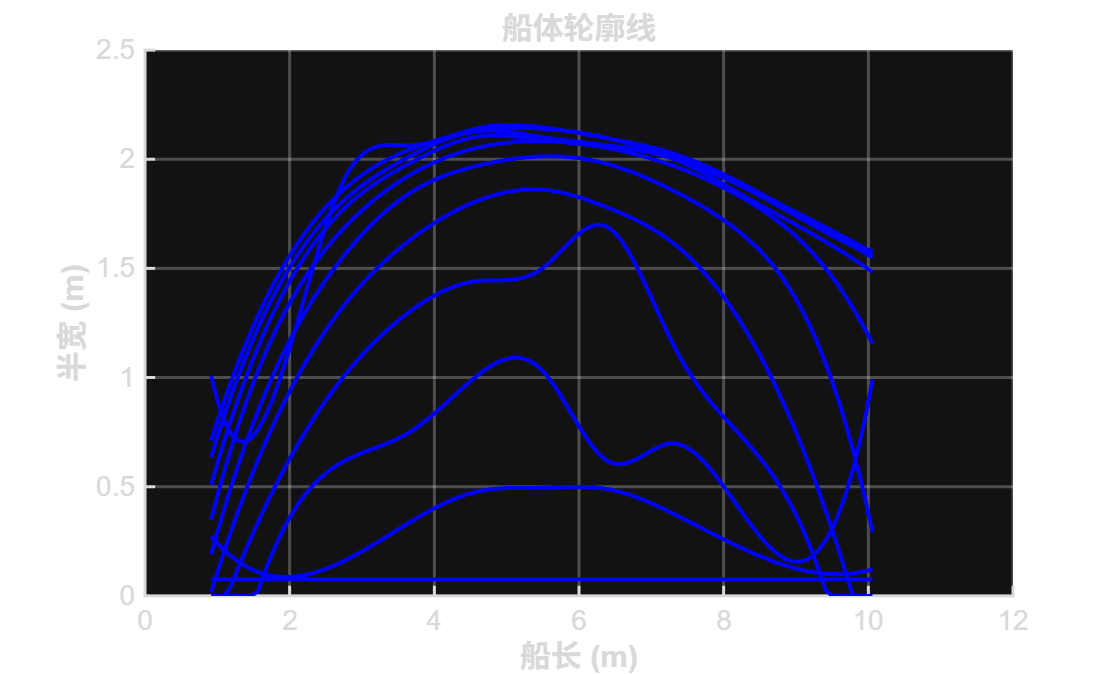


% 设置更大的图形尺寸 - 确保底部宽度至少有A4纸的一半
screen_size = get(0, 'ScreenSize');
fig_width = min(1800, screen_size(3) - 100);  % 最大1800像素，不超过屏幕宽度
fig_height = min(1200, screen_size(4) - 100); % 最大1200像素，不超过屏幕高度

%% 图1: 船体轮廓线
figure('Position', [100, 100, fig_width, fig_height], 'Color', 'white');
hold on;
for i = 1:length(z_levels)
    plot(x_dense, Y_dense(i, :), 'b-', 'LineWidth', 2);
end
xlabel('船长 (m)', 'FontSize', 16, 'FontWeight', 'bold');
ylabel('半宽 (m)', 'FontSize', 16, 'FontWeight', 'bold');
title('船体轮廓线', 'FontSize', 20, 'FontWeight', 'bold');
grid on;
set(gca, 'FontSize', 14, 'LineWidth', 1.5);

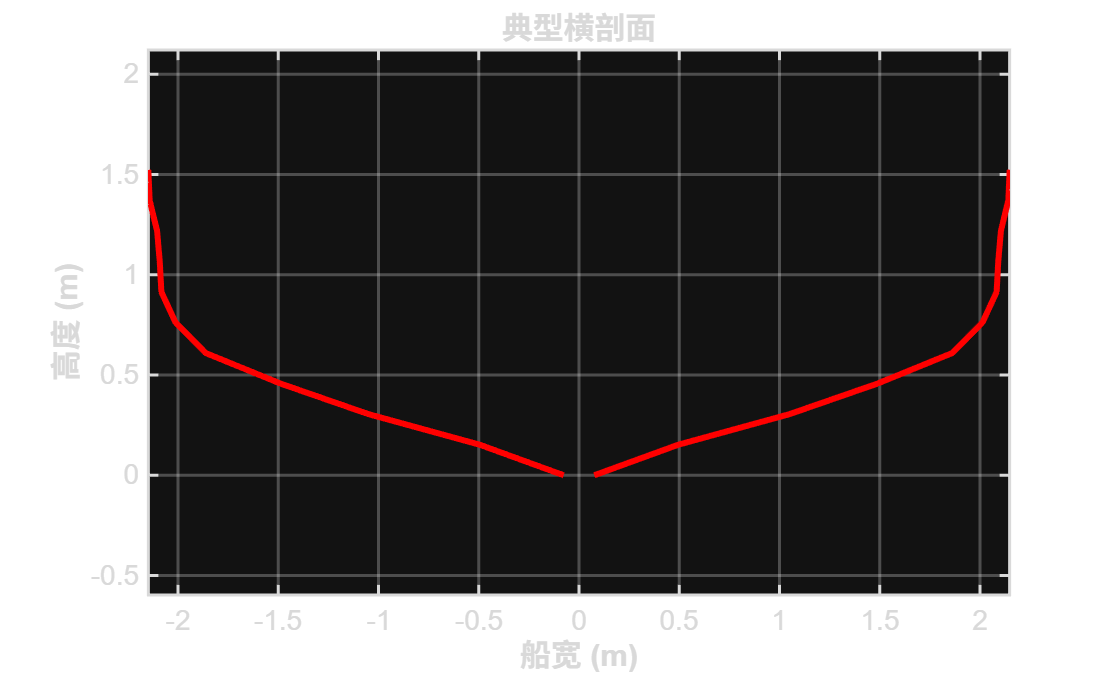


%% 图2: 典型横剖面
figure('Position', [100, 100, fig_width, fig_height], 'Color', 'white');
station_idx = round(num_slices/2);  % 中间站位
plot(Y_dense(:, station_idx), z_levels, 'r-', 'LineWidth', 3);
hold on;
plot(-Y_dense(:, station_idx), z_levels, 'r-', 'LineWidth', 3);
xlabel('船宽 (m)', 'FontSize', 16, 'FontWeight', 'bold');
ylabel('高度 (m)', 'FontSize', 16, 'FontWeight', 'bold');
title('典型横剖面', 'FontSize', 20, 'FontWeight', 'bold');
grid on;
axis equal;
set(gca, 'FontSize', 14, 'LineWidth', 1.5);

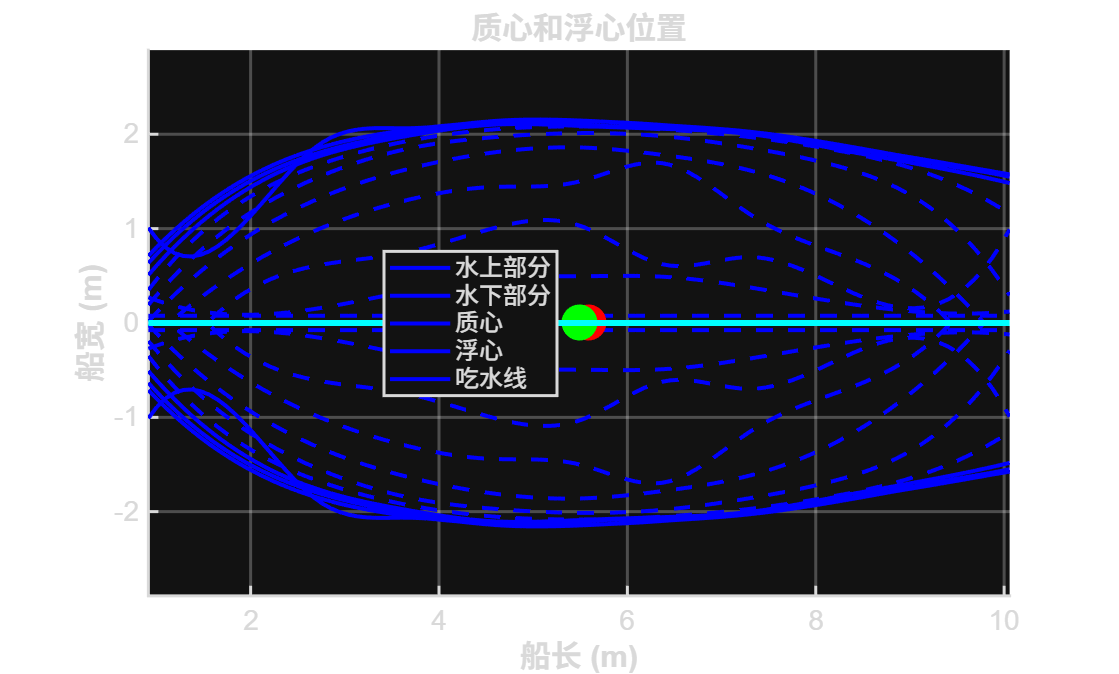


%% 图3: 质心和浮心位置
figure('Position', [100, 100, fig_width, fig_height], 'Color', 'white');
hold on;

waterline = 1.0;  % 选择1.0米吃水线
[buoy_vol, buoy_cent] = calculate_buoyancy_slice(Y_dense, z_levels, x_dense, waterline);

% 绘制船体轮廓
for i = 1:length(z_levels)
    if z_levels(i) >= waterline
        plot(x_dense, Y_dense(i, :), 'b-', 'LineWidth', 2);
        plot(x_dense, -Y_dense(i, :), 'b-', 'LineWidth', 2);
    else
        plot(x_dense, Y_dense(i, :), 'b--', 'LineWidth', 2);
        plot(x_dense, -Y_dense(i, :), 'b--', 'LineWidth', 2);
    end
end

% 标记质心和浮心
plot(center_of_mass_x, 0, 'ro', 'MarkerSize', 15, 'MarkerFaceColor', 'r', 'LineWidth', 3);
plot(buoy_cent(1), 0, 'go', 'MarkerSize', 15, 'MarkerFaceColor', 'g', 'LineWidth', 3);

% 绘制吃水线
plot([min(x_dense), max(x_dense)], [0, 0], 'c-', 'LineWidth', 3);

xlabel('船长 (m)', 'FontSize', 16, 'FontWeight', 'bold');
ylabel('船宽 (m)', 'FontSize', 16, 'FontWeight', 'bold');
title('质心和浮心位置', 'FontSize', 20, 'FontWeight', 'bold');
legend('水上部分', '', '水下部分', '', '质心', '浮心', '吃水线', 'Location', 'best', 'FontSize', 12);
grid on;
axis equal;
set(gca, 'FontSize', 14, 'LineWidth', 1.5);

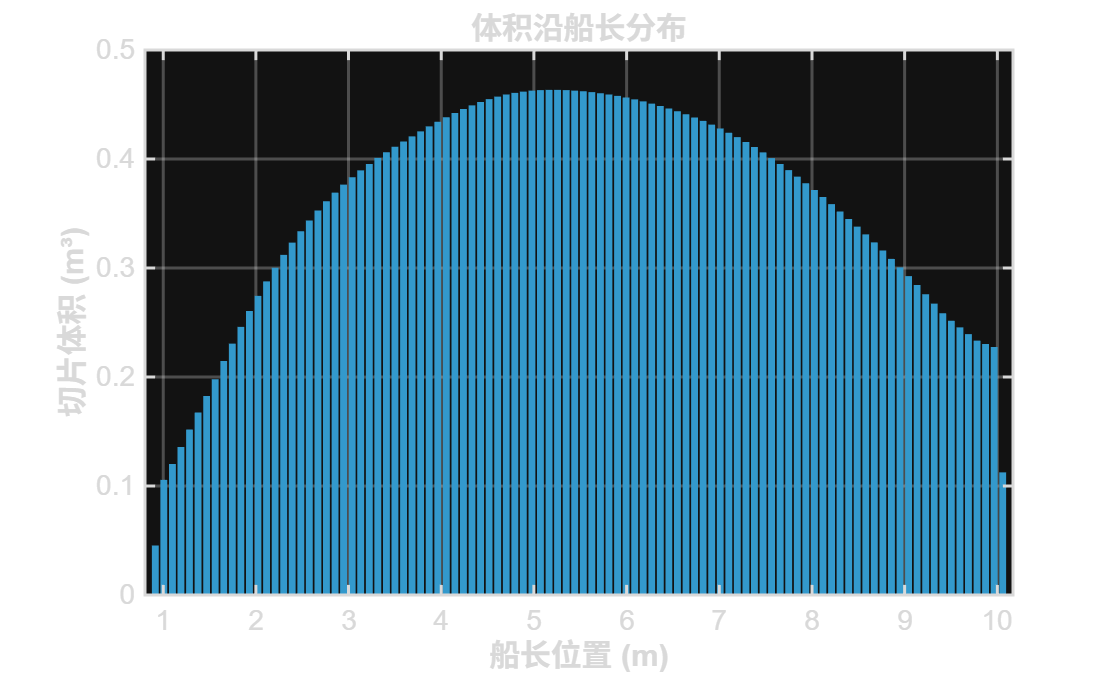


%% 图4: 体积沿船长分布
figure('Position', [100, 100, fig_width, fig_height], 'Color', 'white');
bar(x_dense, slice_volumes, 'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'none');
xlabel('船长位置 (m)', 'FontSize', 16, 'FontWeight', 'bold');
ylabel('切片体积 (m³)', 'FontSize', 16, 'FontWeight', 'bold');
title('体积沿船长分布', 'FontSize', 20, 'FontWeight', 'bold');
grid on;
set(gca, 'FontSize', 14, 'LineWidth', 1.5);

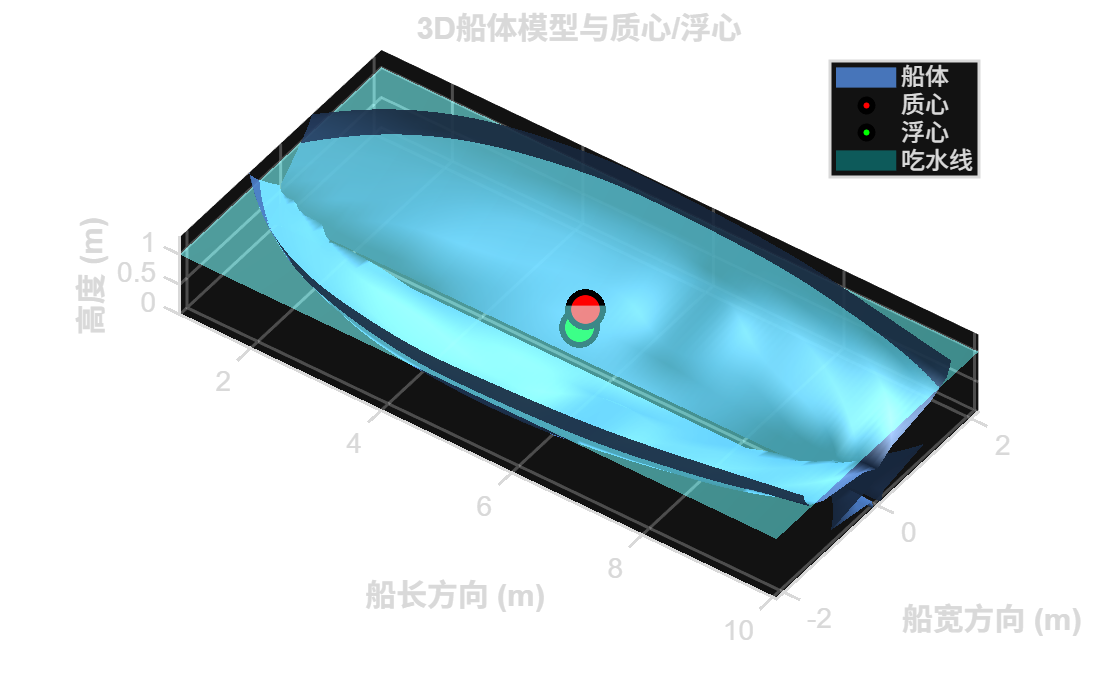


%% 图5: 3D船体建模
figure('Position', [100, 100, fig_width, fig_height], 'Color', 'white');

% 创建3D网格
[X_3D, Z_3D] = meshgrid(x_dense, z_levels);
Y_3D_right = Y_dense;

% 创建左舷数据
Y_3D_left = -Y_dense;

% 绘制右舷
surf(X_3D, Y_3D_right, Z_3D, 'FaceAlpha', 0.9, 'EdgeColor', 'none', ...
     'FaceColor', [0.3 0.5 0.8], 'FaceLighting', 'gouraud');
hold on;

% 绘制左舷
surf(X_3D, Y_3D_left, Z_3D, 'FaceAlpha', 0.9, 'EdgeColor', 'none', ...
     'FaceColor', [0.3 0.5 0.8], 'FaceLighting', 'gouraud');

% 标记质心
scatter3(center_of_mass_x, 0, center_of_mass_z, 300, 'r', 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 3);

% 标记浮心
scatter3(buoy_cent(1), 0, buoy_cent(3), 300, 'g', 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 3);

% 绘制吃水线平面
[x_water, y_water] = meshgrid(linspace(min(x_dense), max(x_dense), 30), ...
                     linspace(min(Y_3D_left(:)), max(Y_3D_right(:)), 30));
z_water = ones(size(x_water)) * waterline;
surf(x_water, y_water, z_water, 'FaceAlpha', 0.3, 'FaceColor', 'cyan', 'EdgeColor', 'none');

% 设置图形属性
xlabel('船长方向 (m)', 'FontSize', 16, 'FontWeight', 'bold');
ylabel('船宽方向 (m)', 'FontSize', 16, 'FontWeight', 'bold');
zlabel('高度 (m)', 'FontSize', 16, 'FontWeight', 'bold');
title('3D船体模型与质心/浮心', 'FontSize', 20, 'FontWeight', 'bold');

% 添加光照
light('Position', [1 1 1], 'Style', 'infinite');
light('Position', [-1 1 1], 'Style', 'infinite');
lighting gouraud;

% 设置视角和坐标轴
view(40, 25);
grid on;
axis equal;
set(gca, 'FontSize', 14, 'LineWidth', 1.5);

% 添加图例
legend('船体', '', '质心', '浮心', '吃水线', 'Location', 'best', 'FontSize', 12);


fprintf('\n计算完成！\n');


计算完成！


fprintf('已生成5个独立的图形，尺寸为 %d x %d 像素\n', fig_width, fig_height);

已生成5个独立的图形，尺寸为 1.606667e+03 x 9.666667e+02 像素


fprintf('图形列表：\n');

图形列表：


fprintf('  1. 船体轮廓线\n');

  1. 船体轮廓线


fprintf('  2. 典型横剖面\n');

  2. 典型横剖面


fprintf('  3. 质心和浮心位置\n');

  3. 质心和浮心位置


fprintf('  4. 体积沿船长分布\n');

  4. 体积沿船长分布


fprintf('  5. 3D船体模型\n');

  5. 3D船体模型
